Task 1

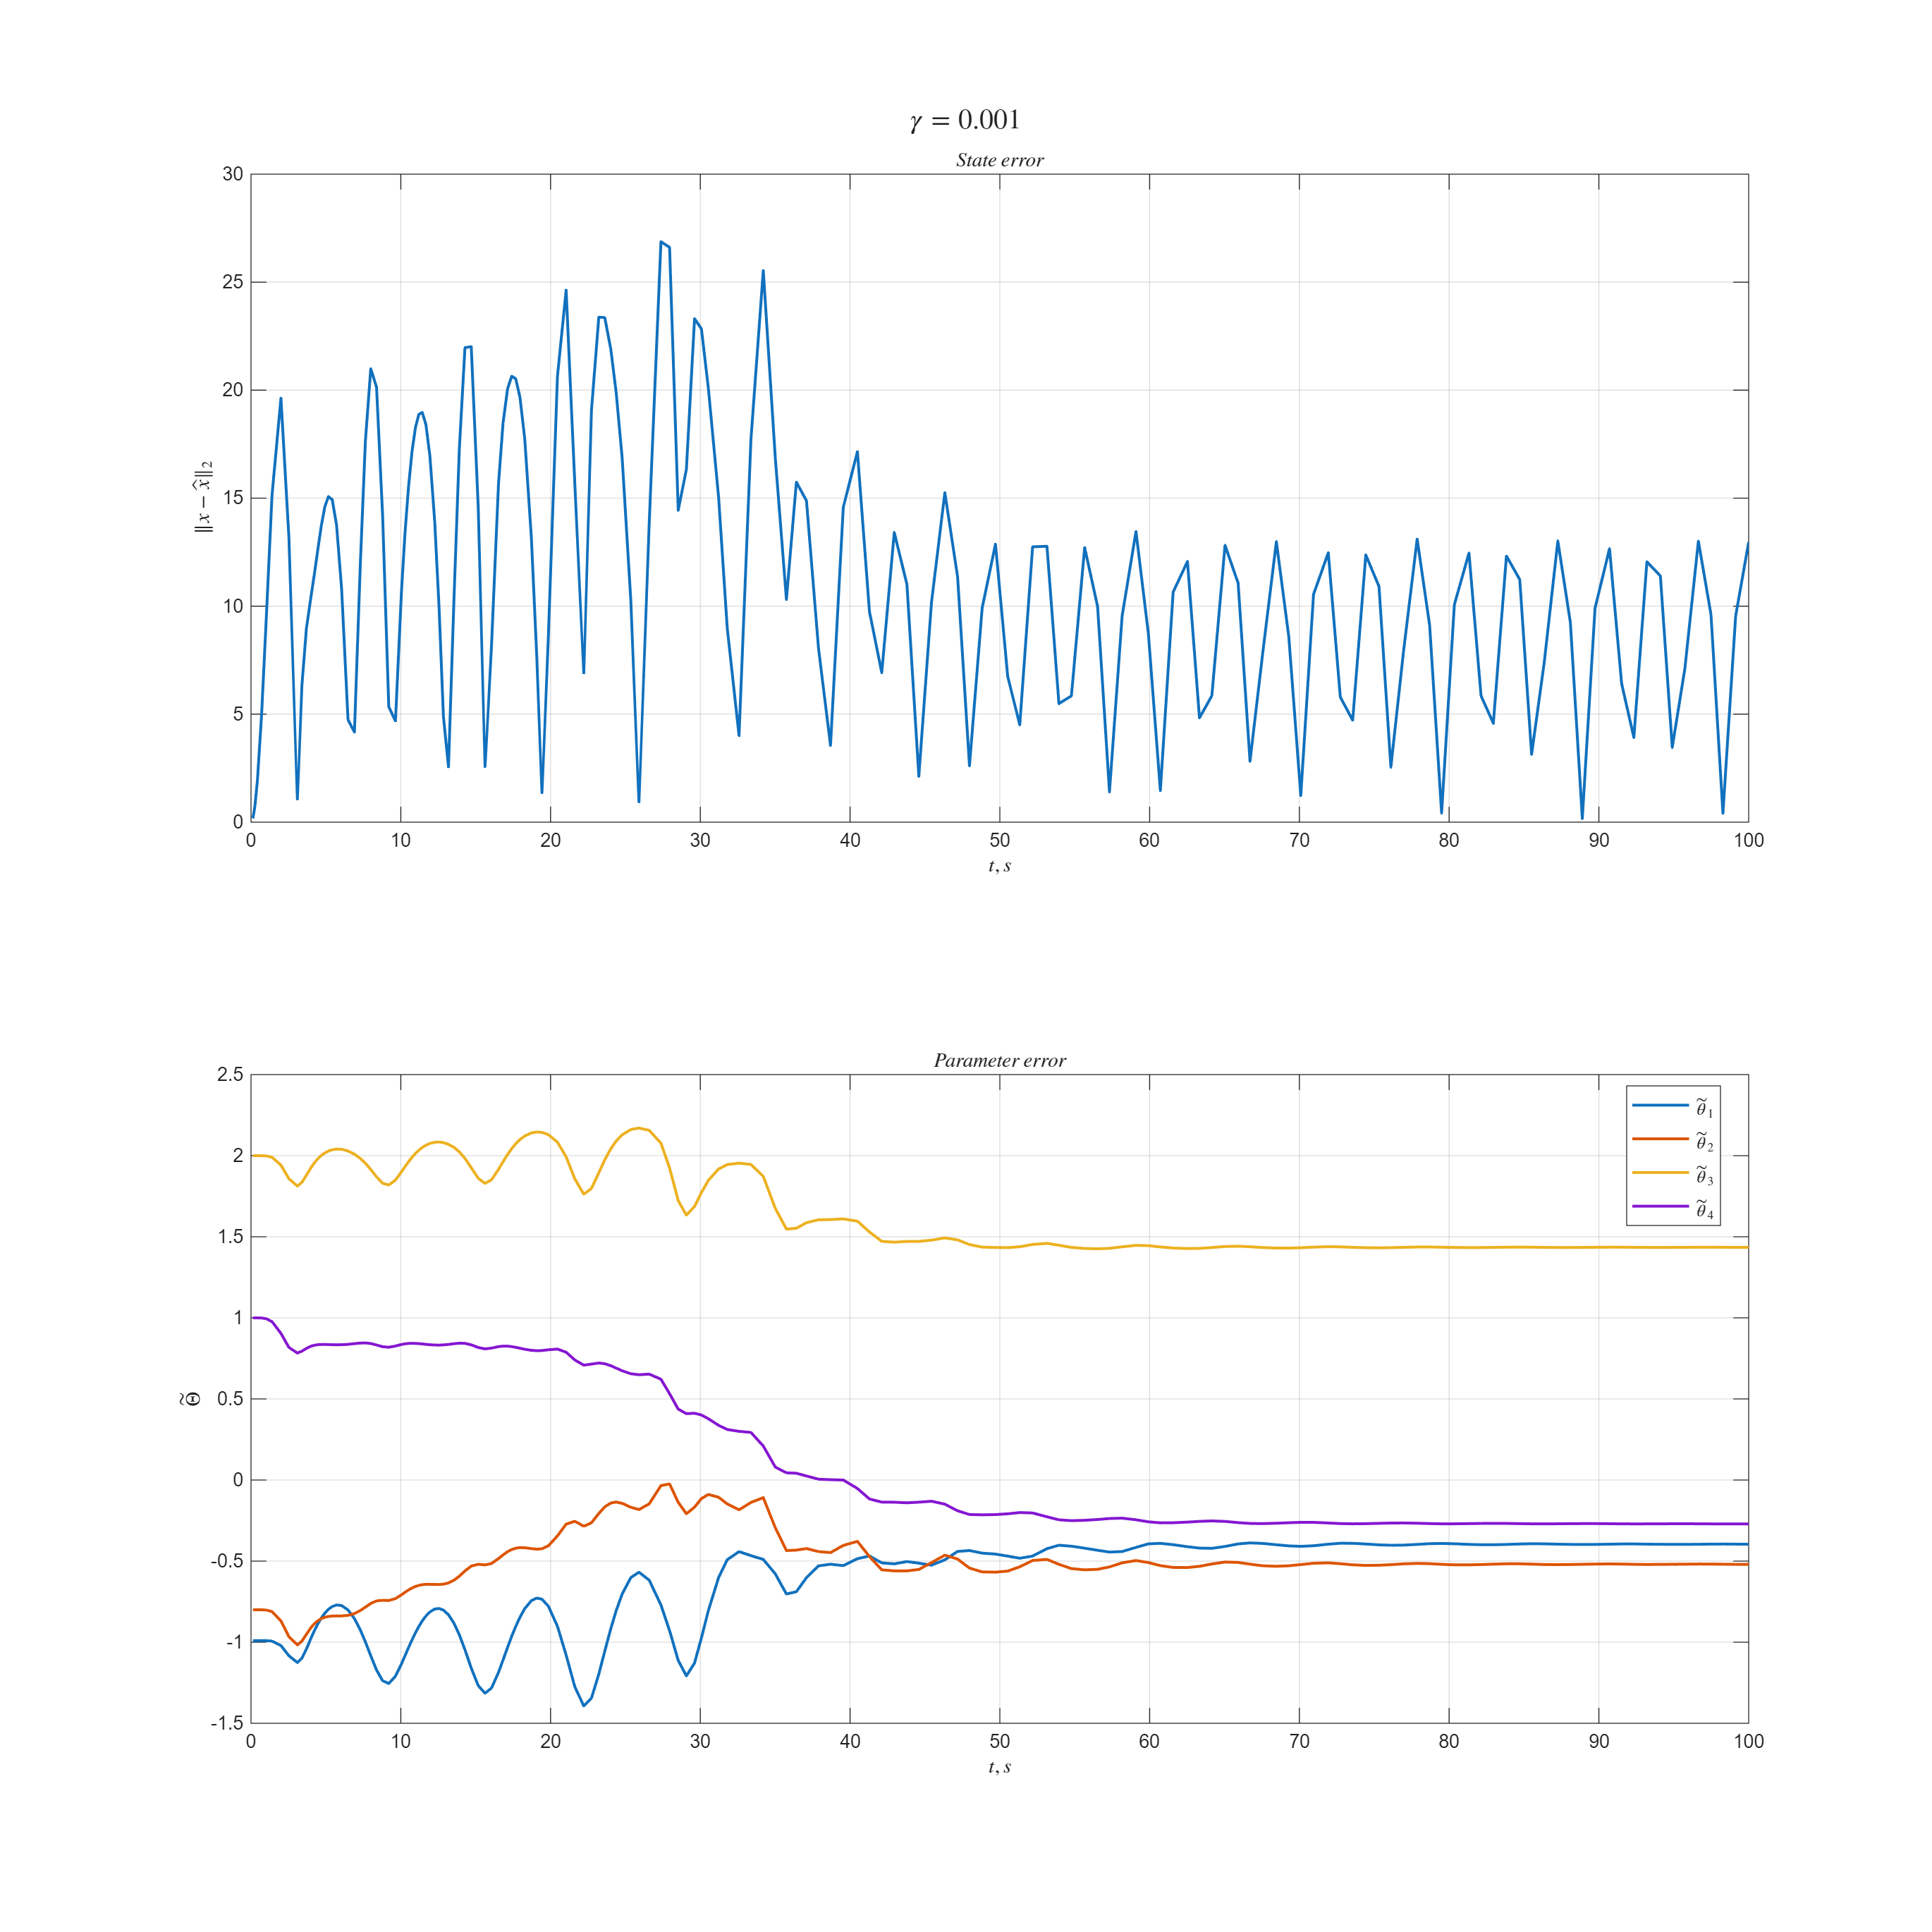

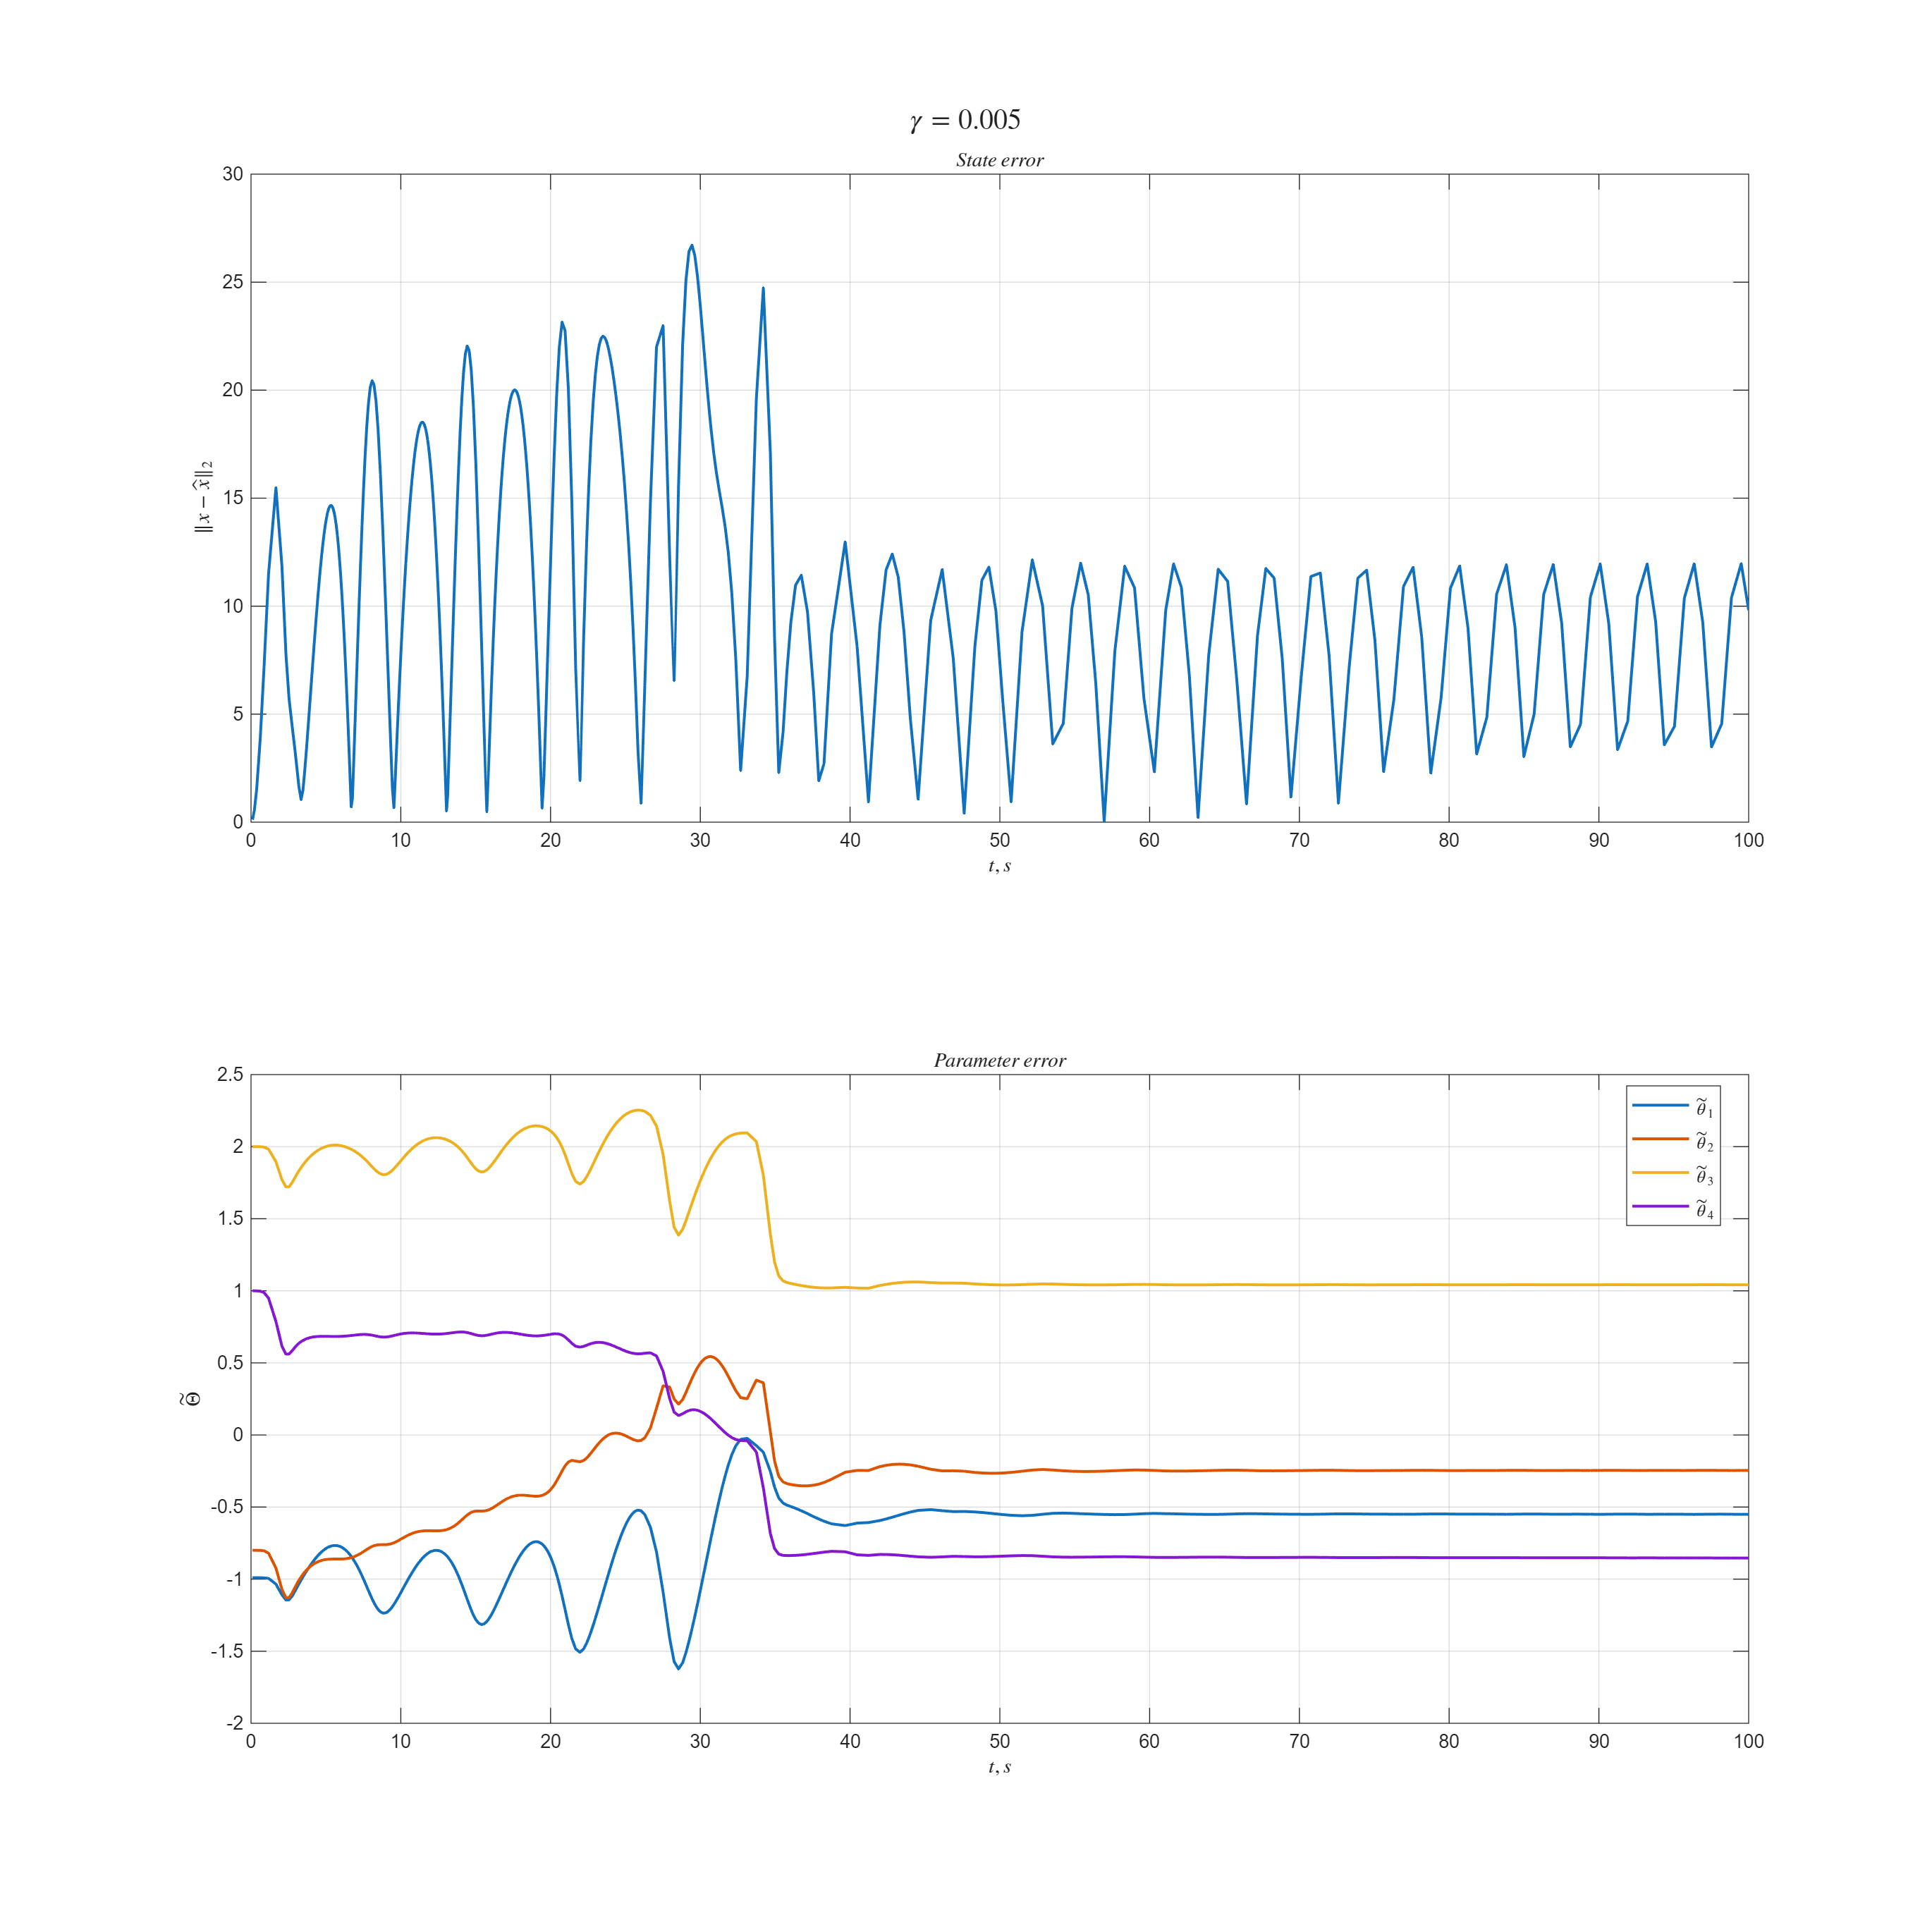

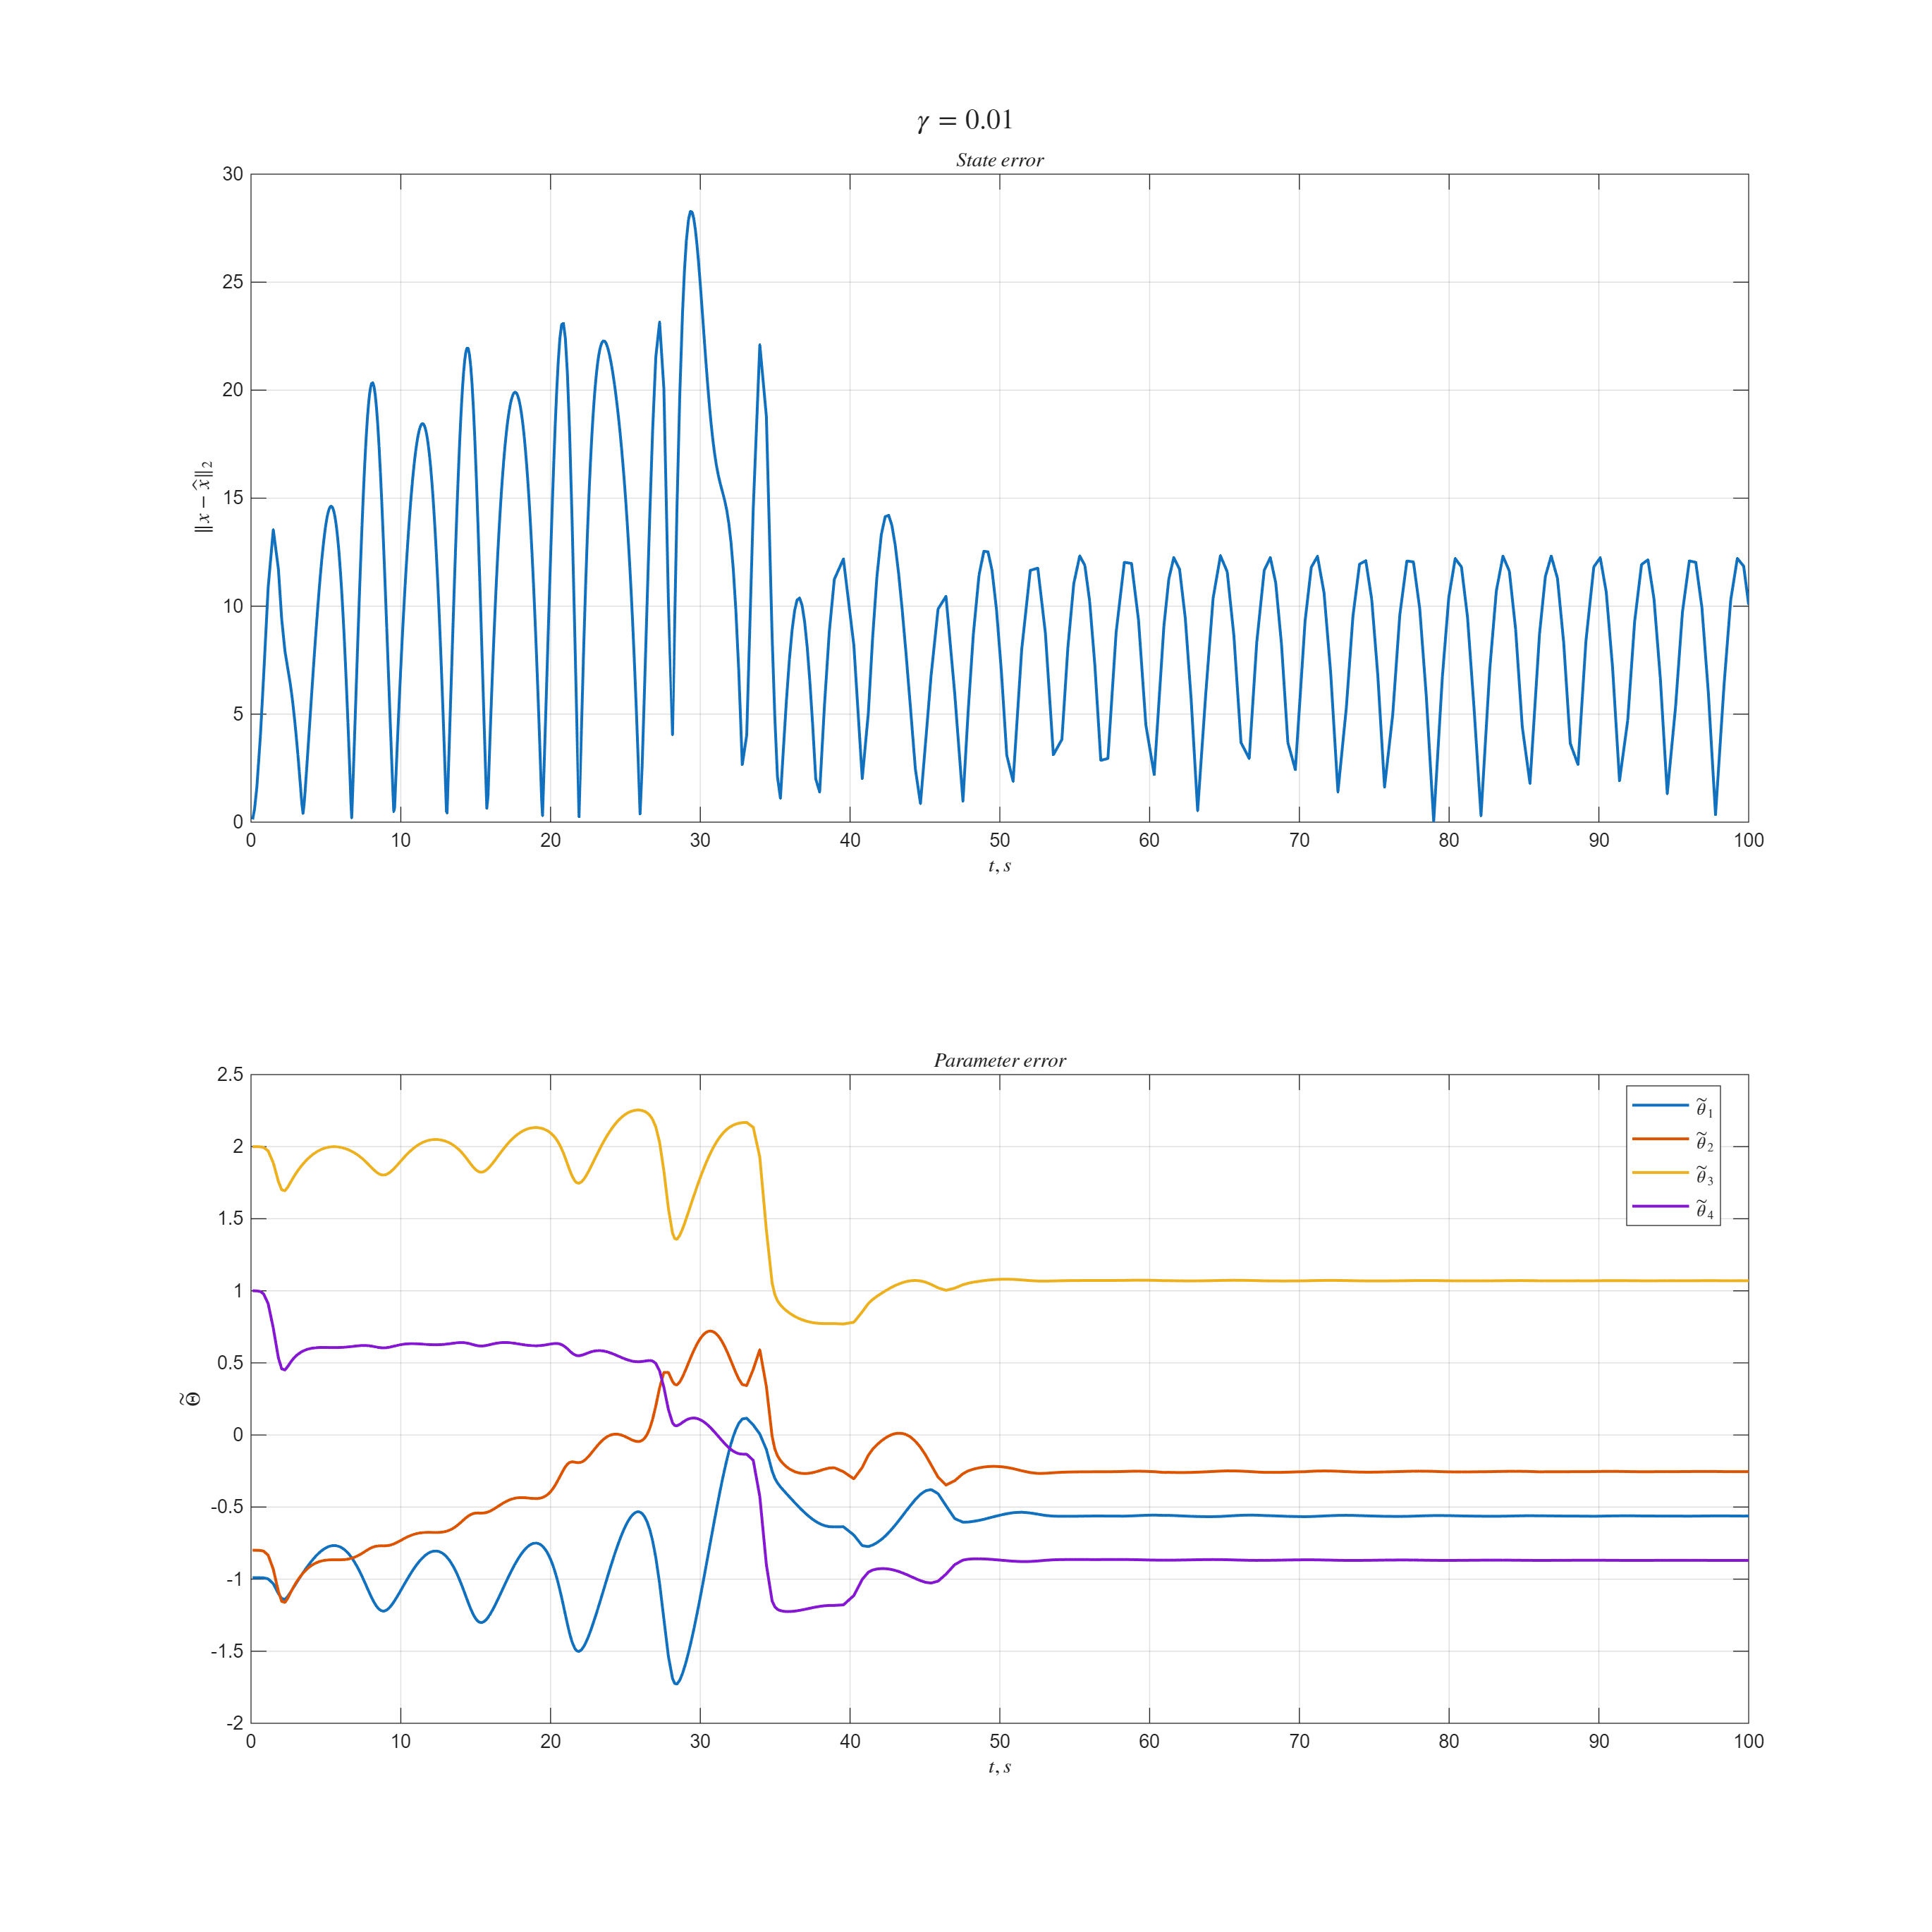

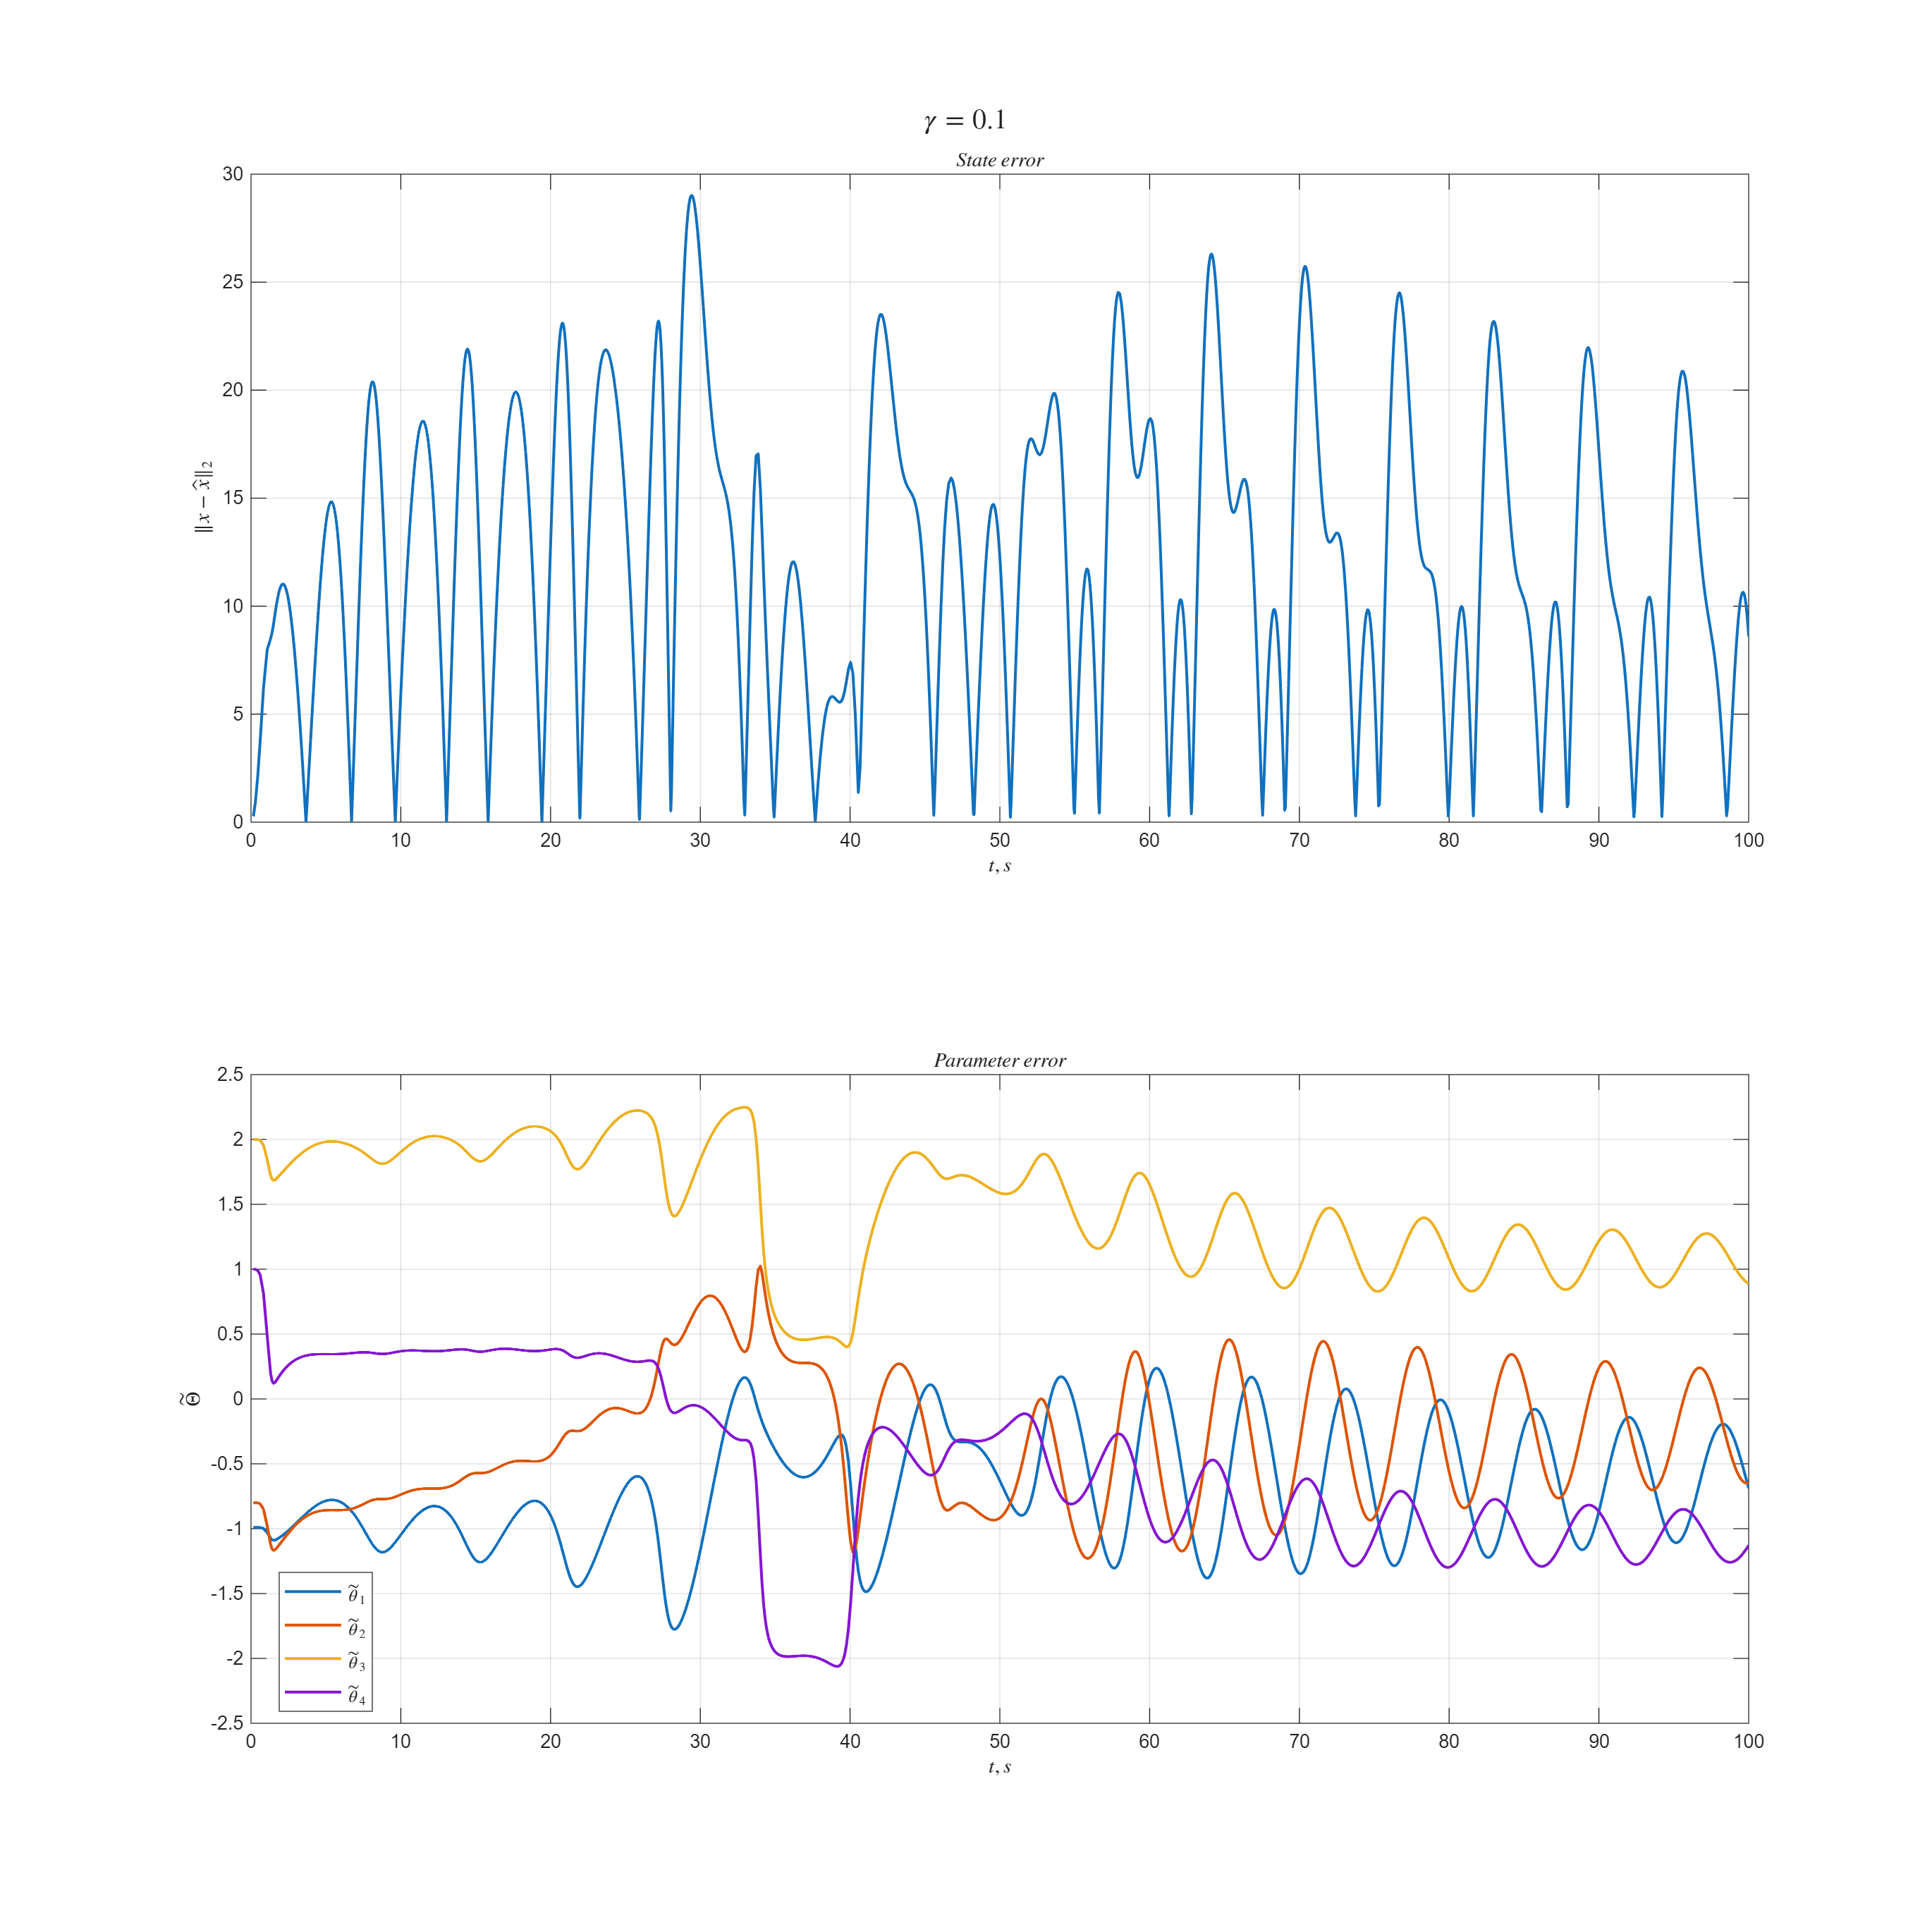

k_1 = 0.2;
k_0 = 0.01;

gamma_values = [0.001 0.005 0.01 0.1];
task1 = 1;
simtime = 100;

folder = "C:/Users/Nickolay/Desktop/ITMO-courses/7_term/Adaptive_and_robust_control/lab6/tex/images/";

for gamma = gamma_values
    out = sim("lab6.slx", simtime);

    fig = figure('Position', [100, 100, 1600, 1600]);

    subplot(2,1,1);
    plot(out.state_error.Time, out.state_error.Data, LineWidth=1.5);
    xlabel("$t,s$", Interpreter="latex");
    ylabel("$\|x-\hat{x}\|_2$", Interpreter="latex");
    title("$State~error$", Interpreter="latex");
    grid on;

    subplot(2,1,2);
    plot(out.Theta_error.Time, out.Theta_error.Data, LineWidth=1.5);
    xlabel("$t,s$", Interpreter="latex");
    ylabel("$\tilde{\Theta}$", Interpreter="latex");
    title("$Parameter~error$", Interpreter="latex");
    legend(["$\tilde{\theta}_1$", "$\tilde{\theta}_2$", ...
        "$\tilde{\theta}_3$", "$\tilde{\theta}_4$"], ...
       Interpreter="latex", Location="best");
    grid on;

    sgtitle(sprintf('$\\gamma = %g$', gamma), Interpreter="latex");

    filename = sprintf('lab6_task%d_gamma_%g.png', task1, gamma);
    exportgraphics(fig, fullfile(folder, filename), 'Resolution', 600);
end

Task 2

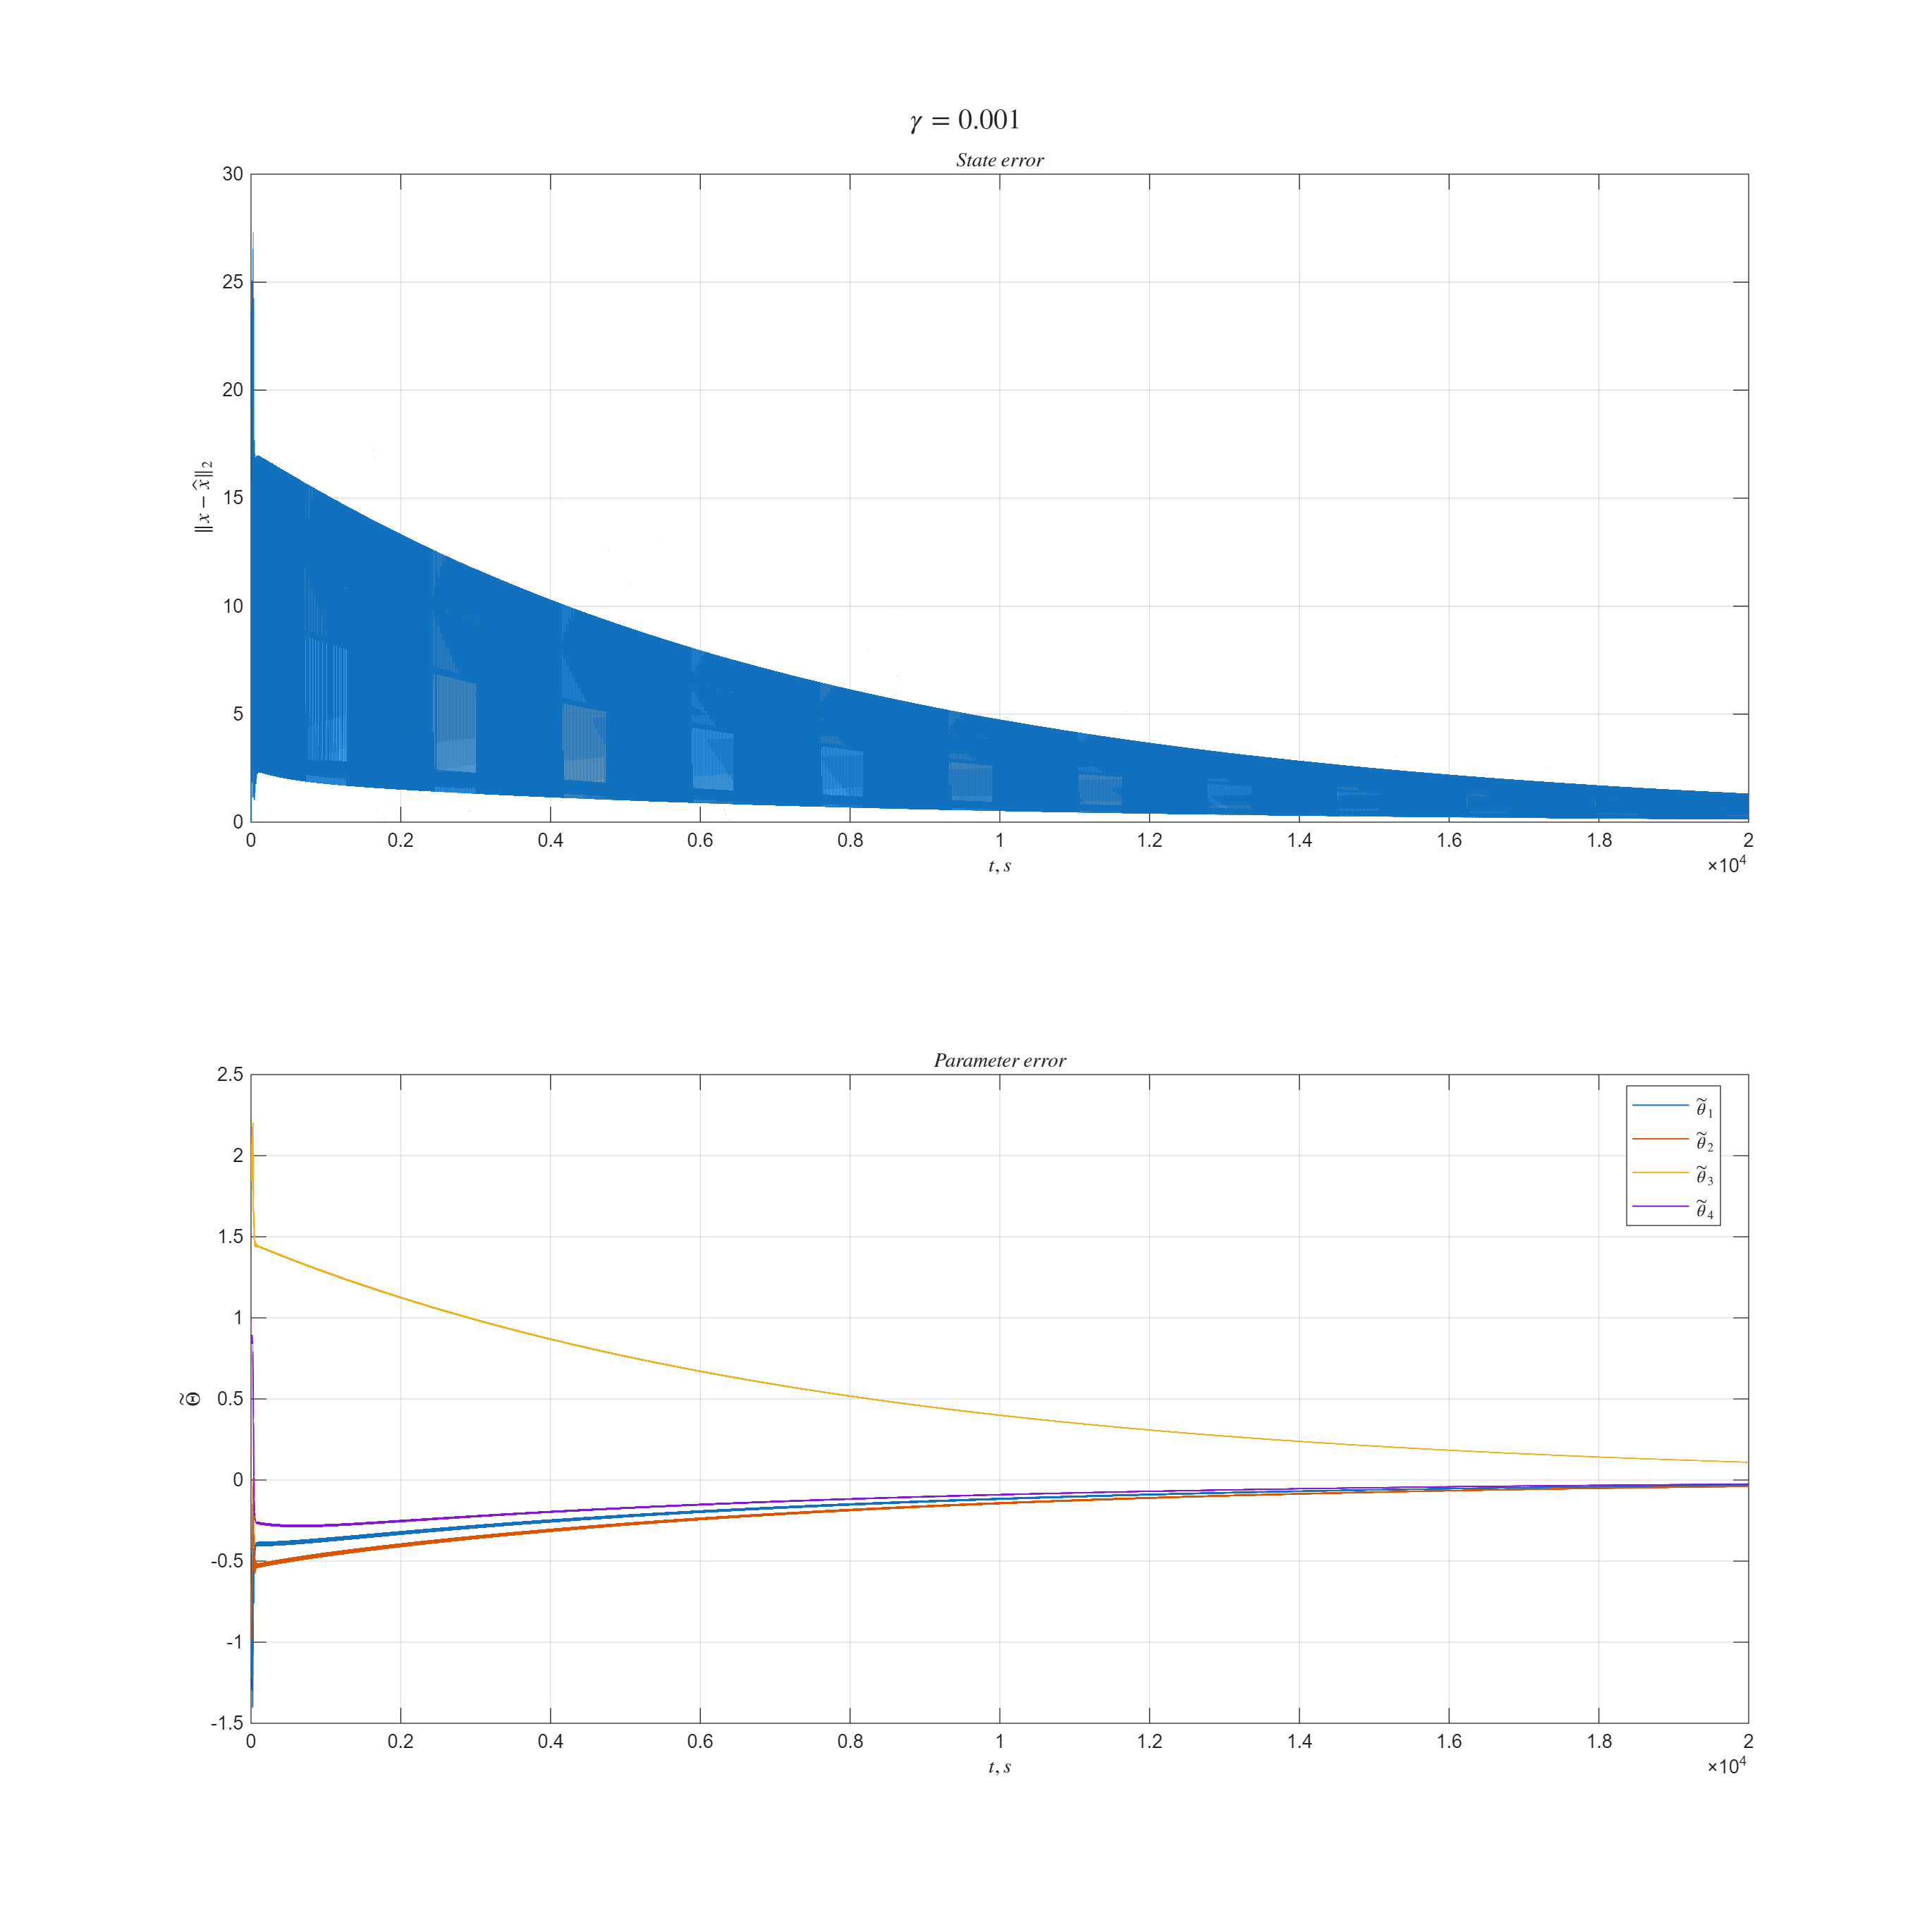

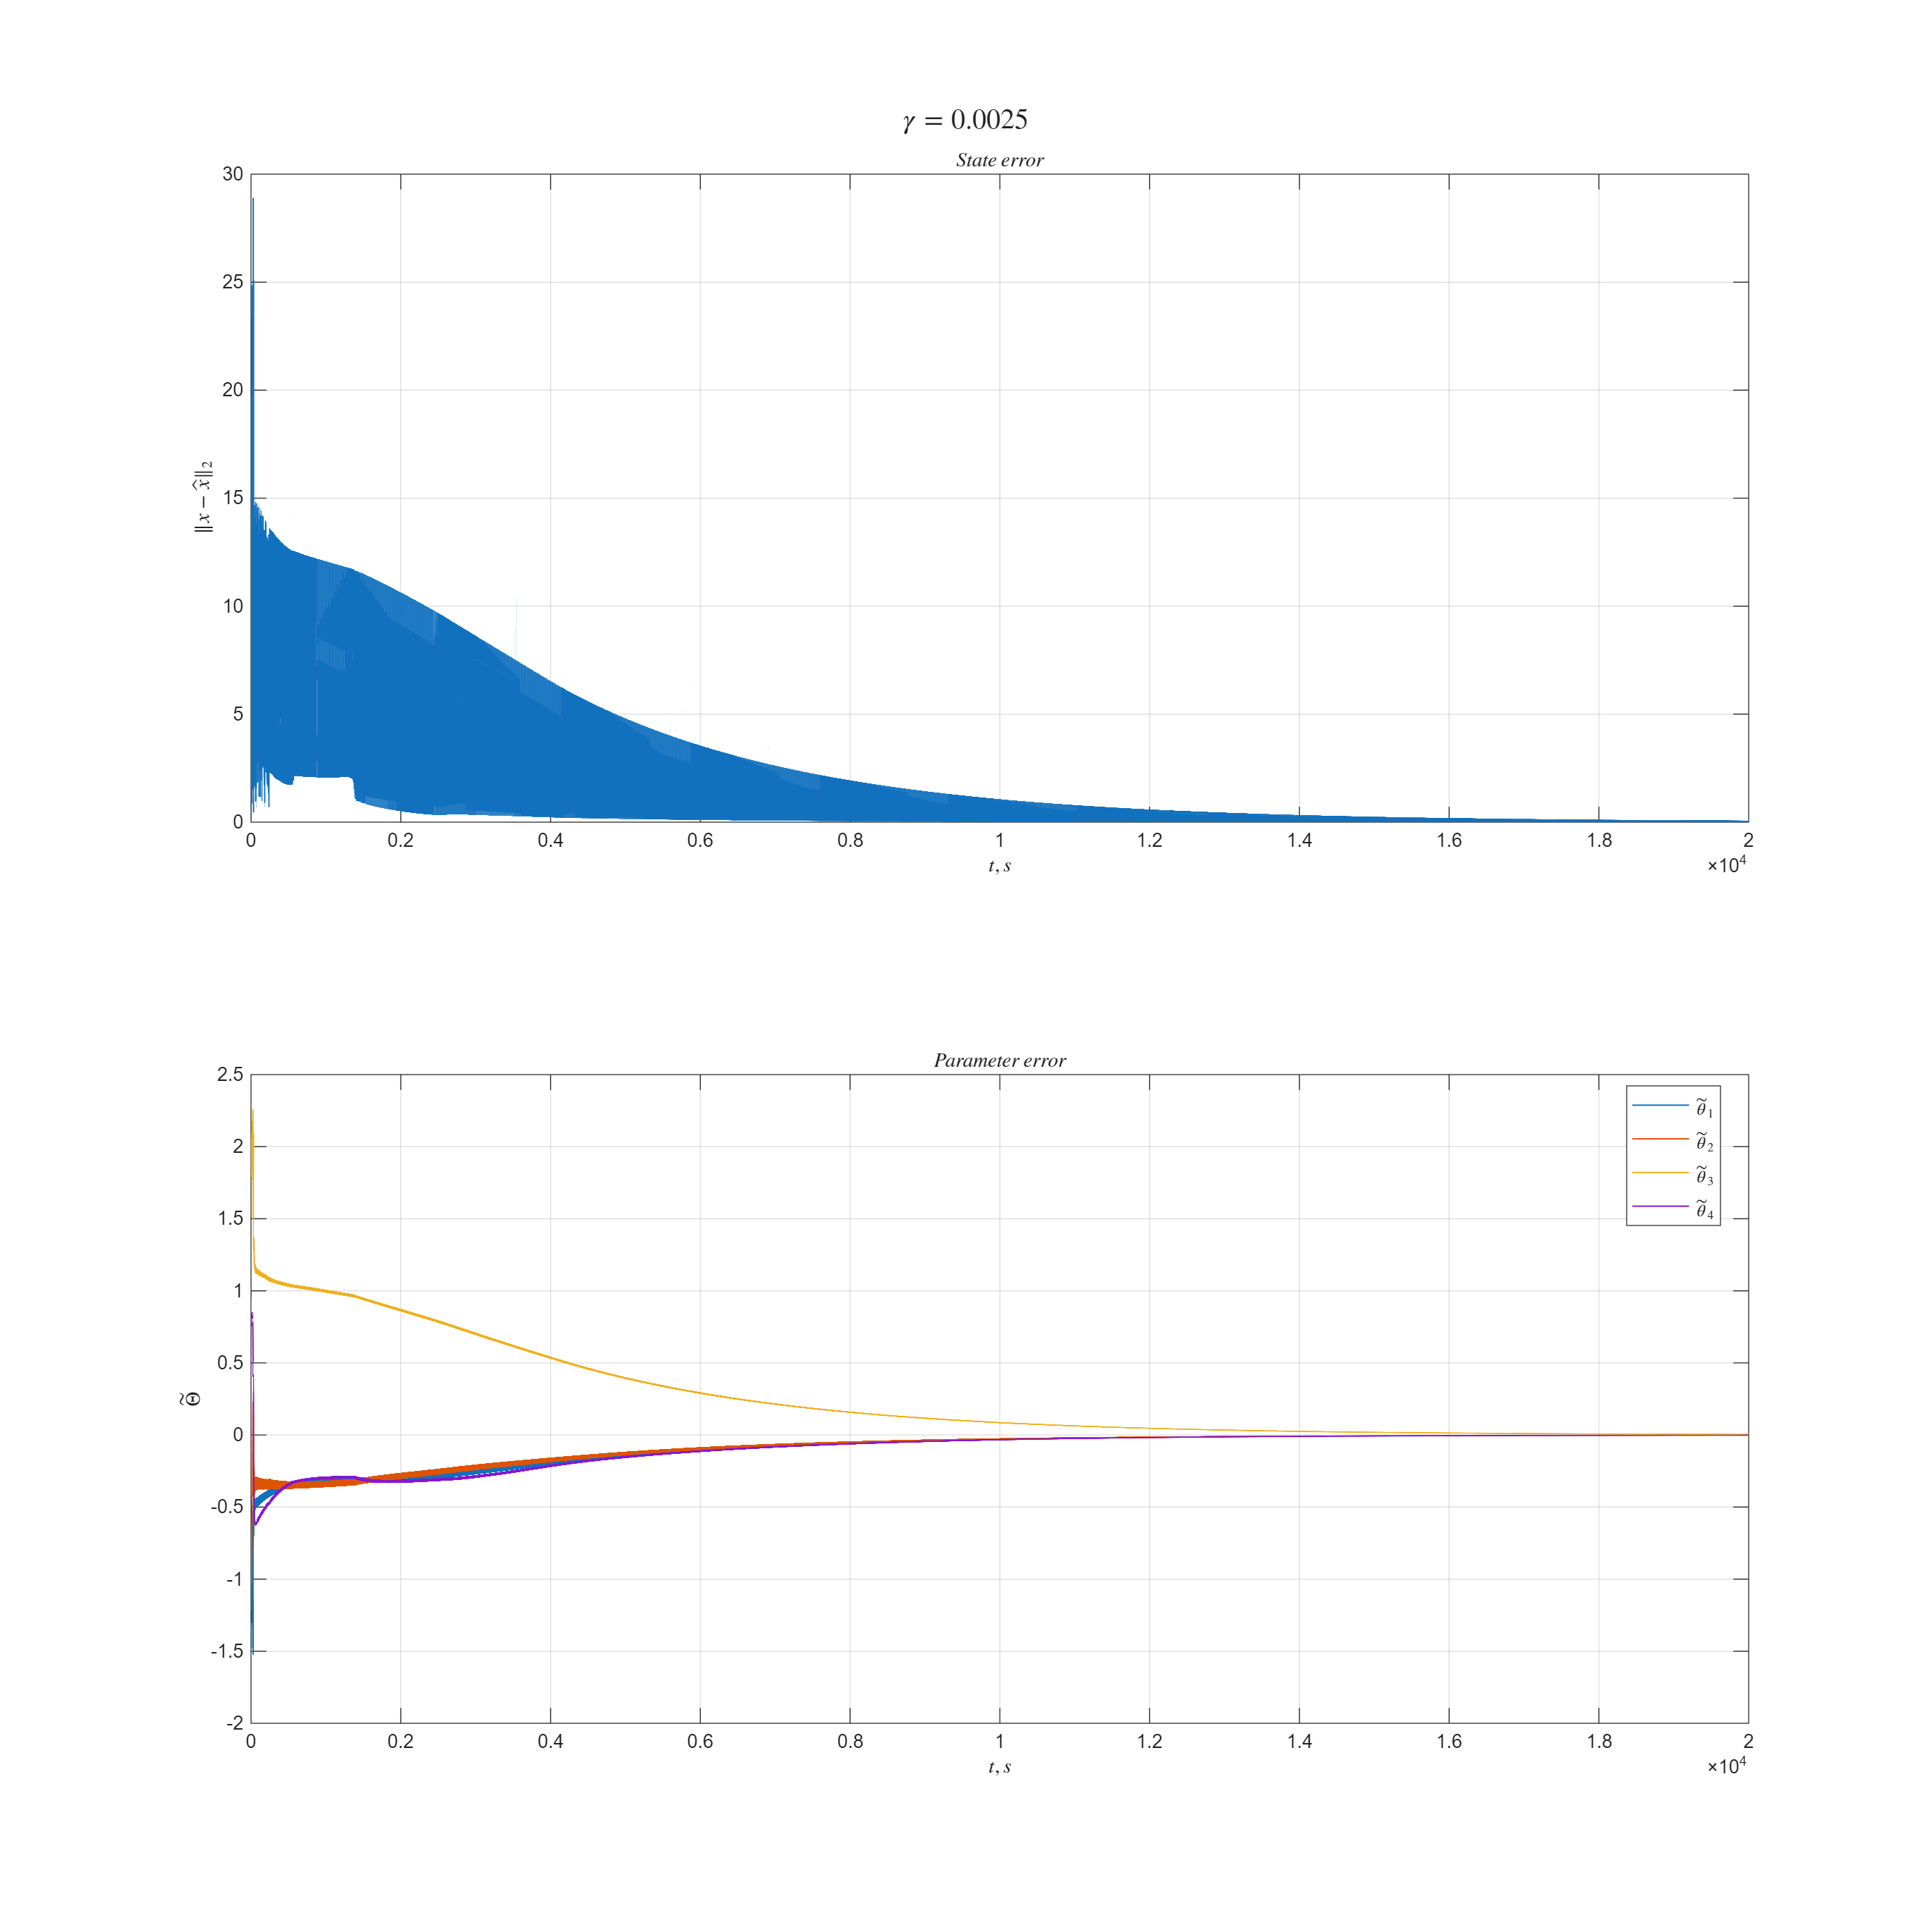

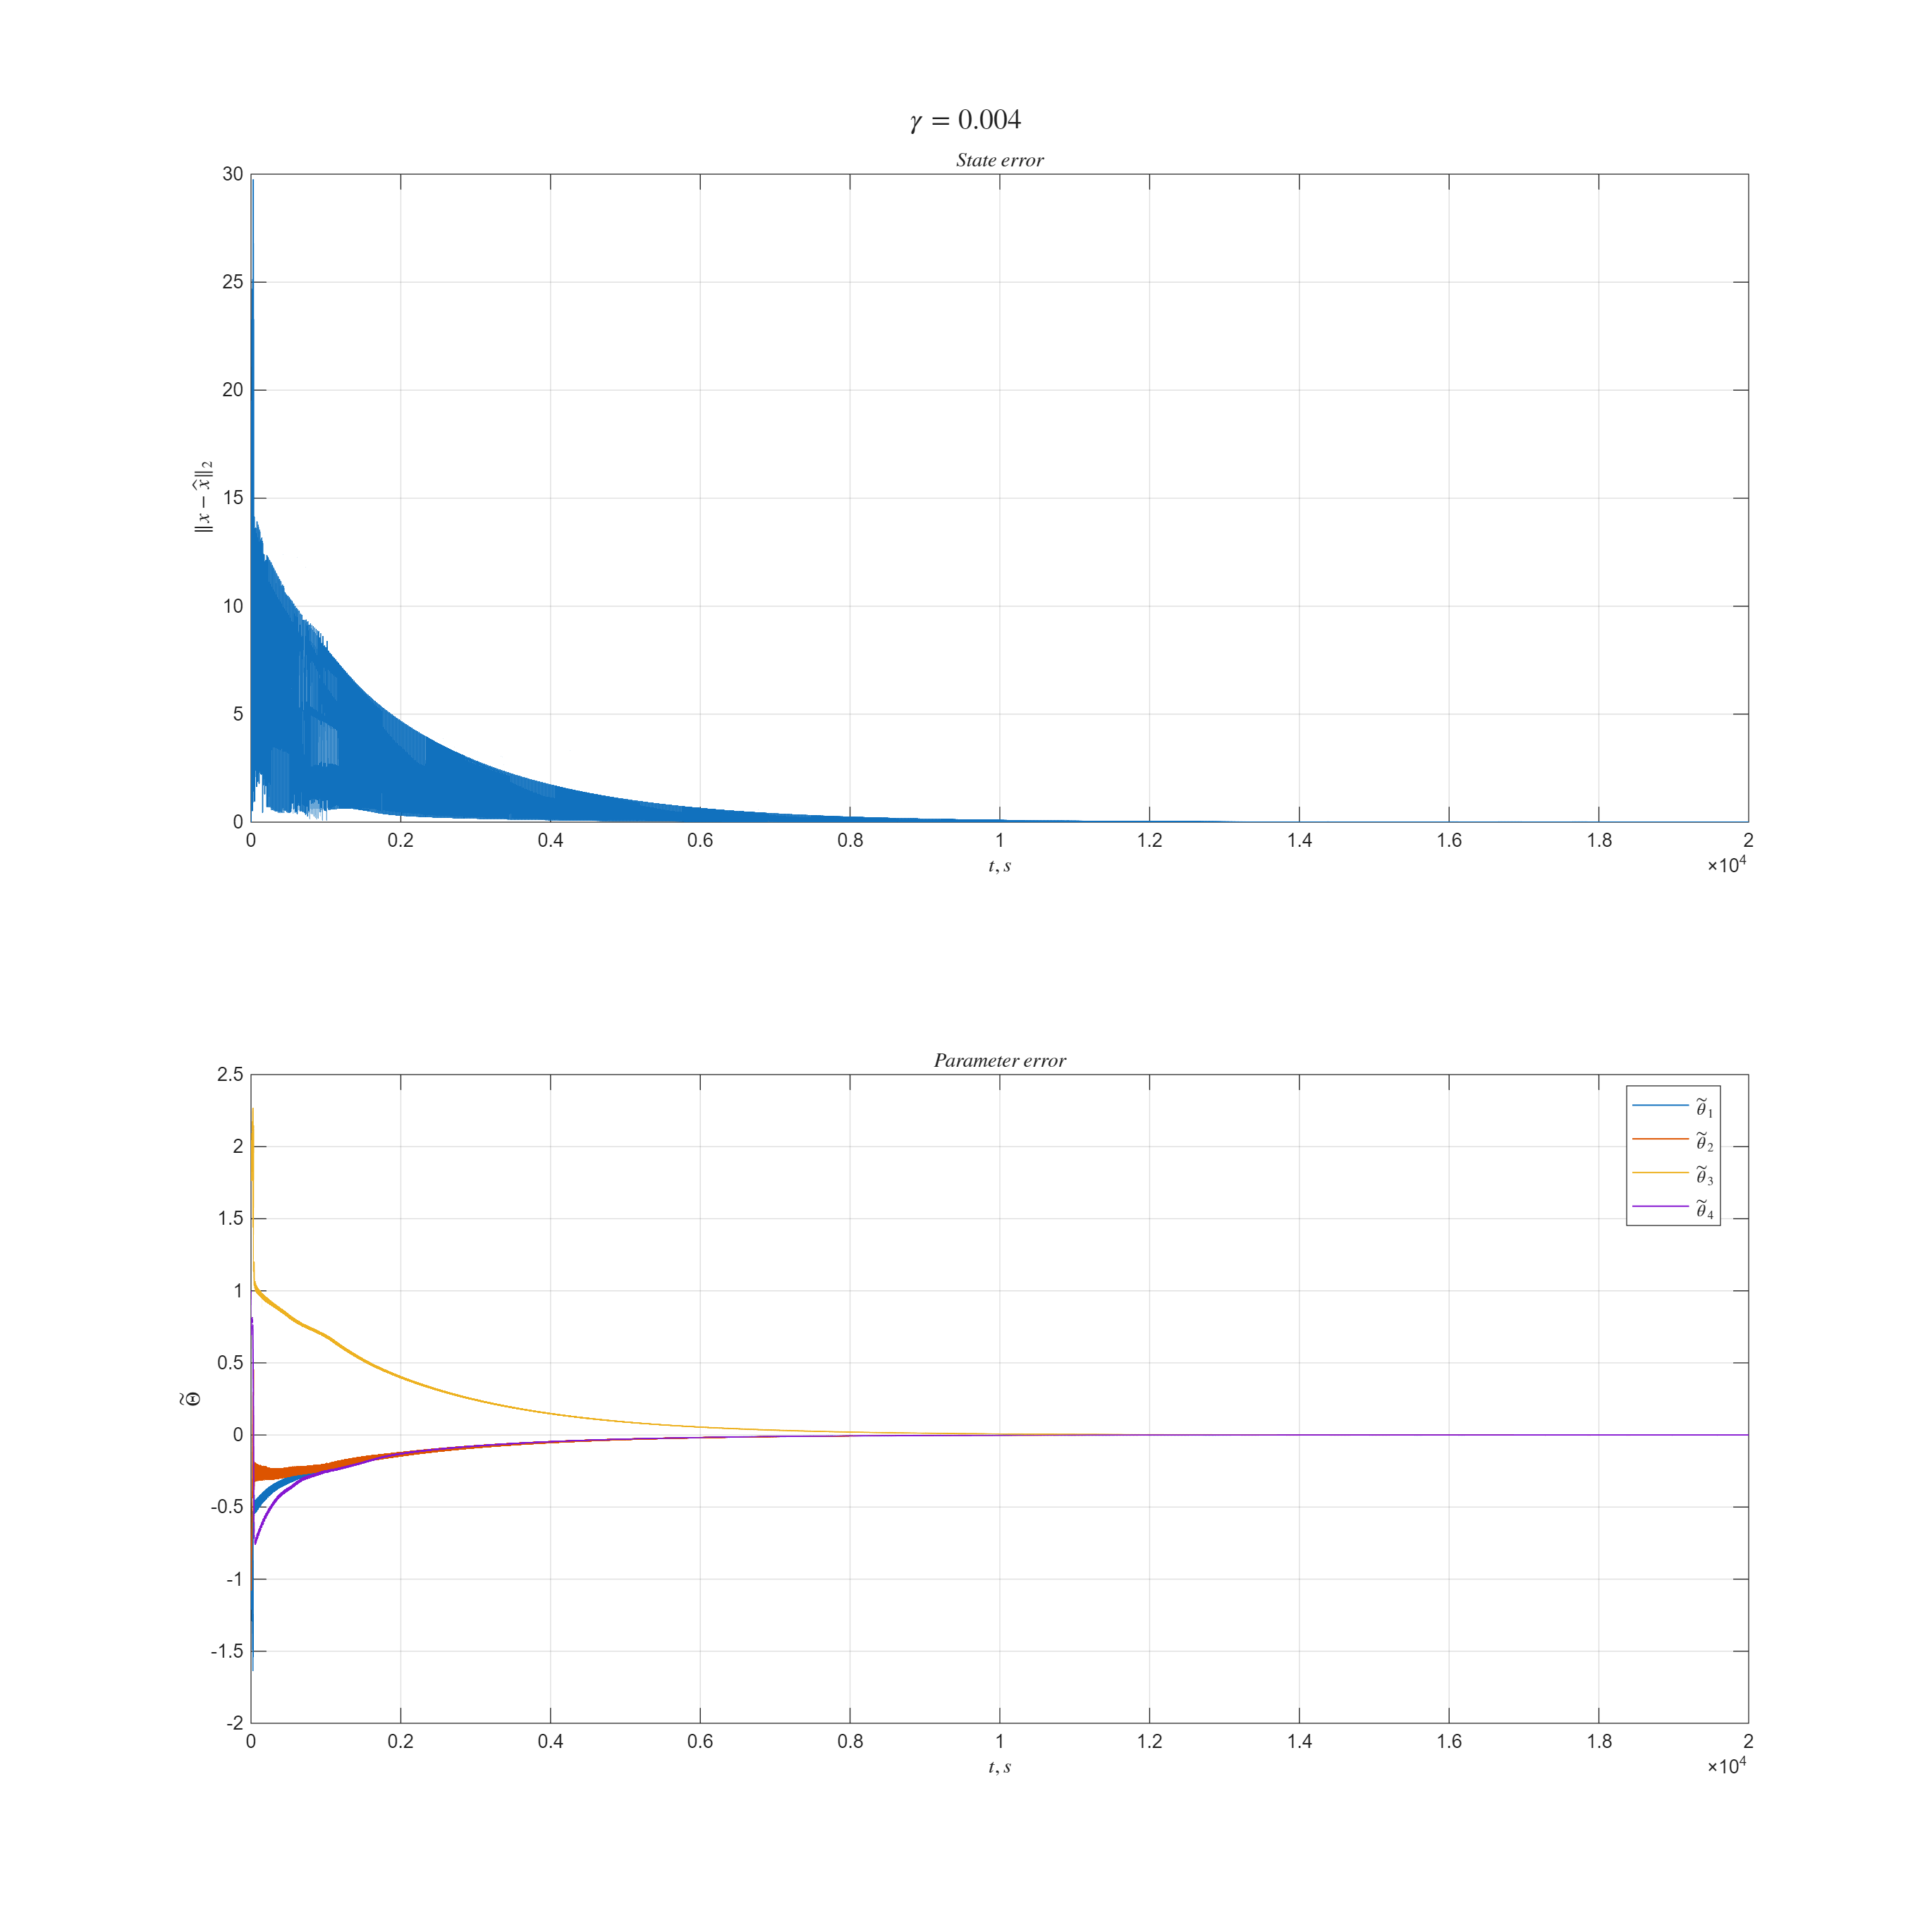

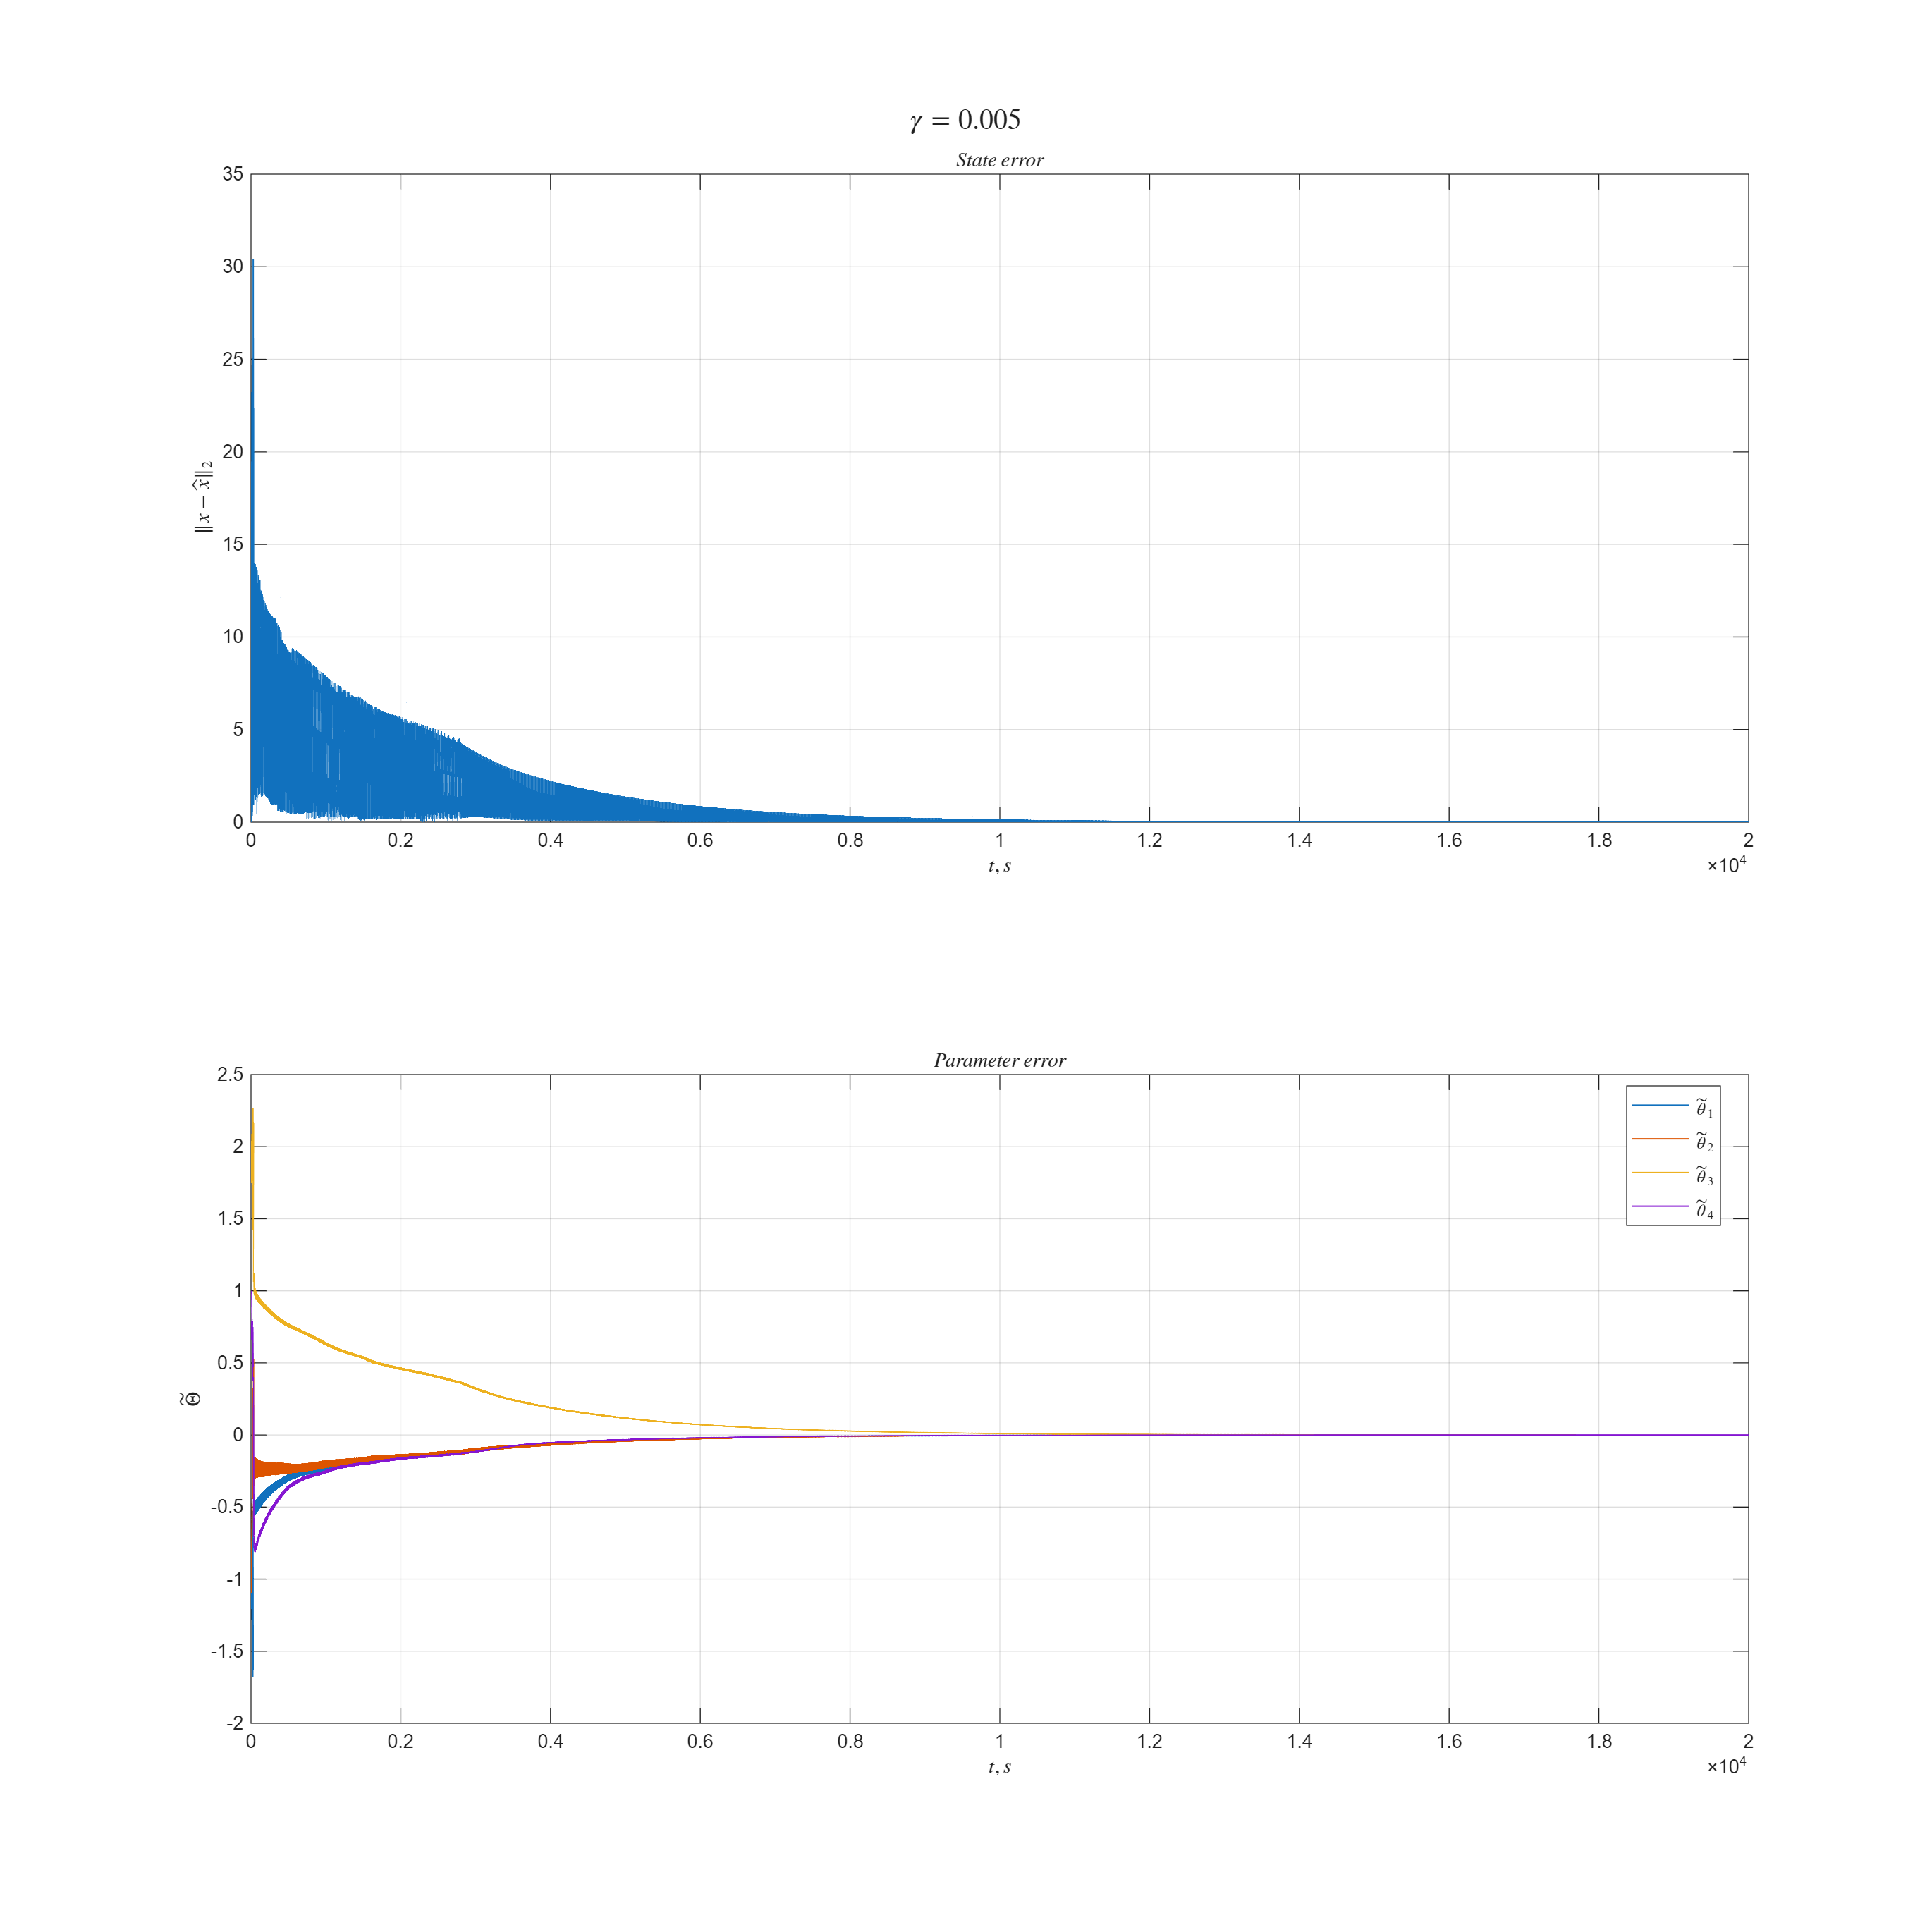

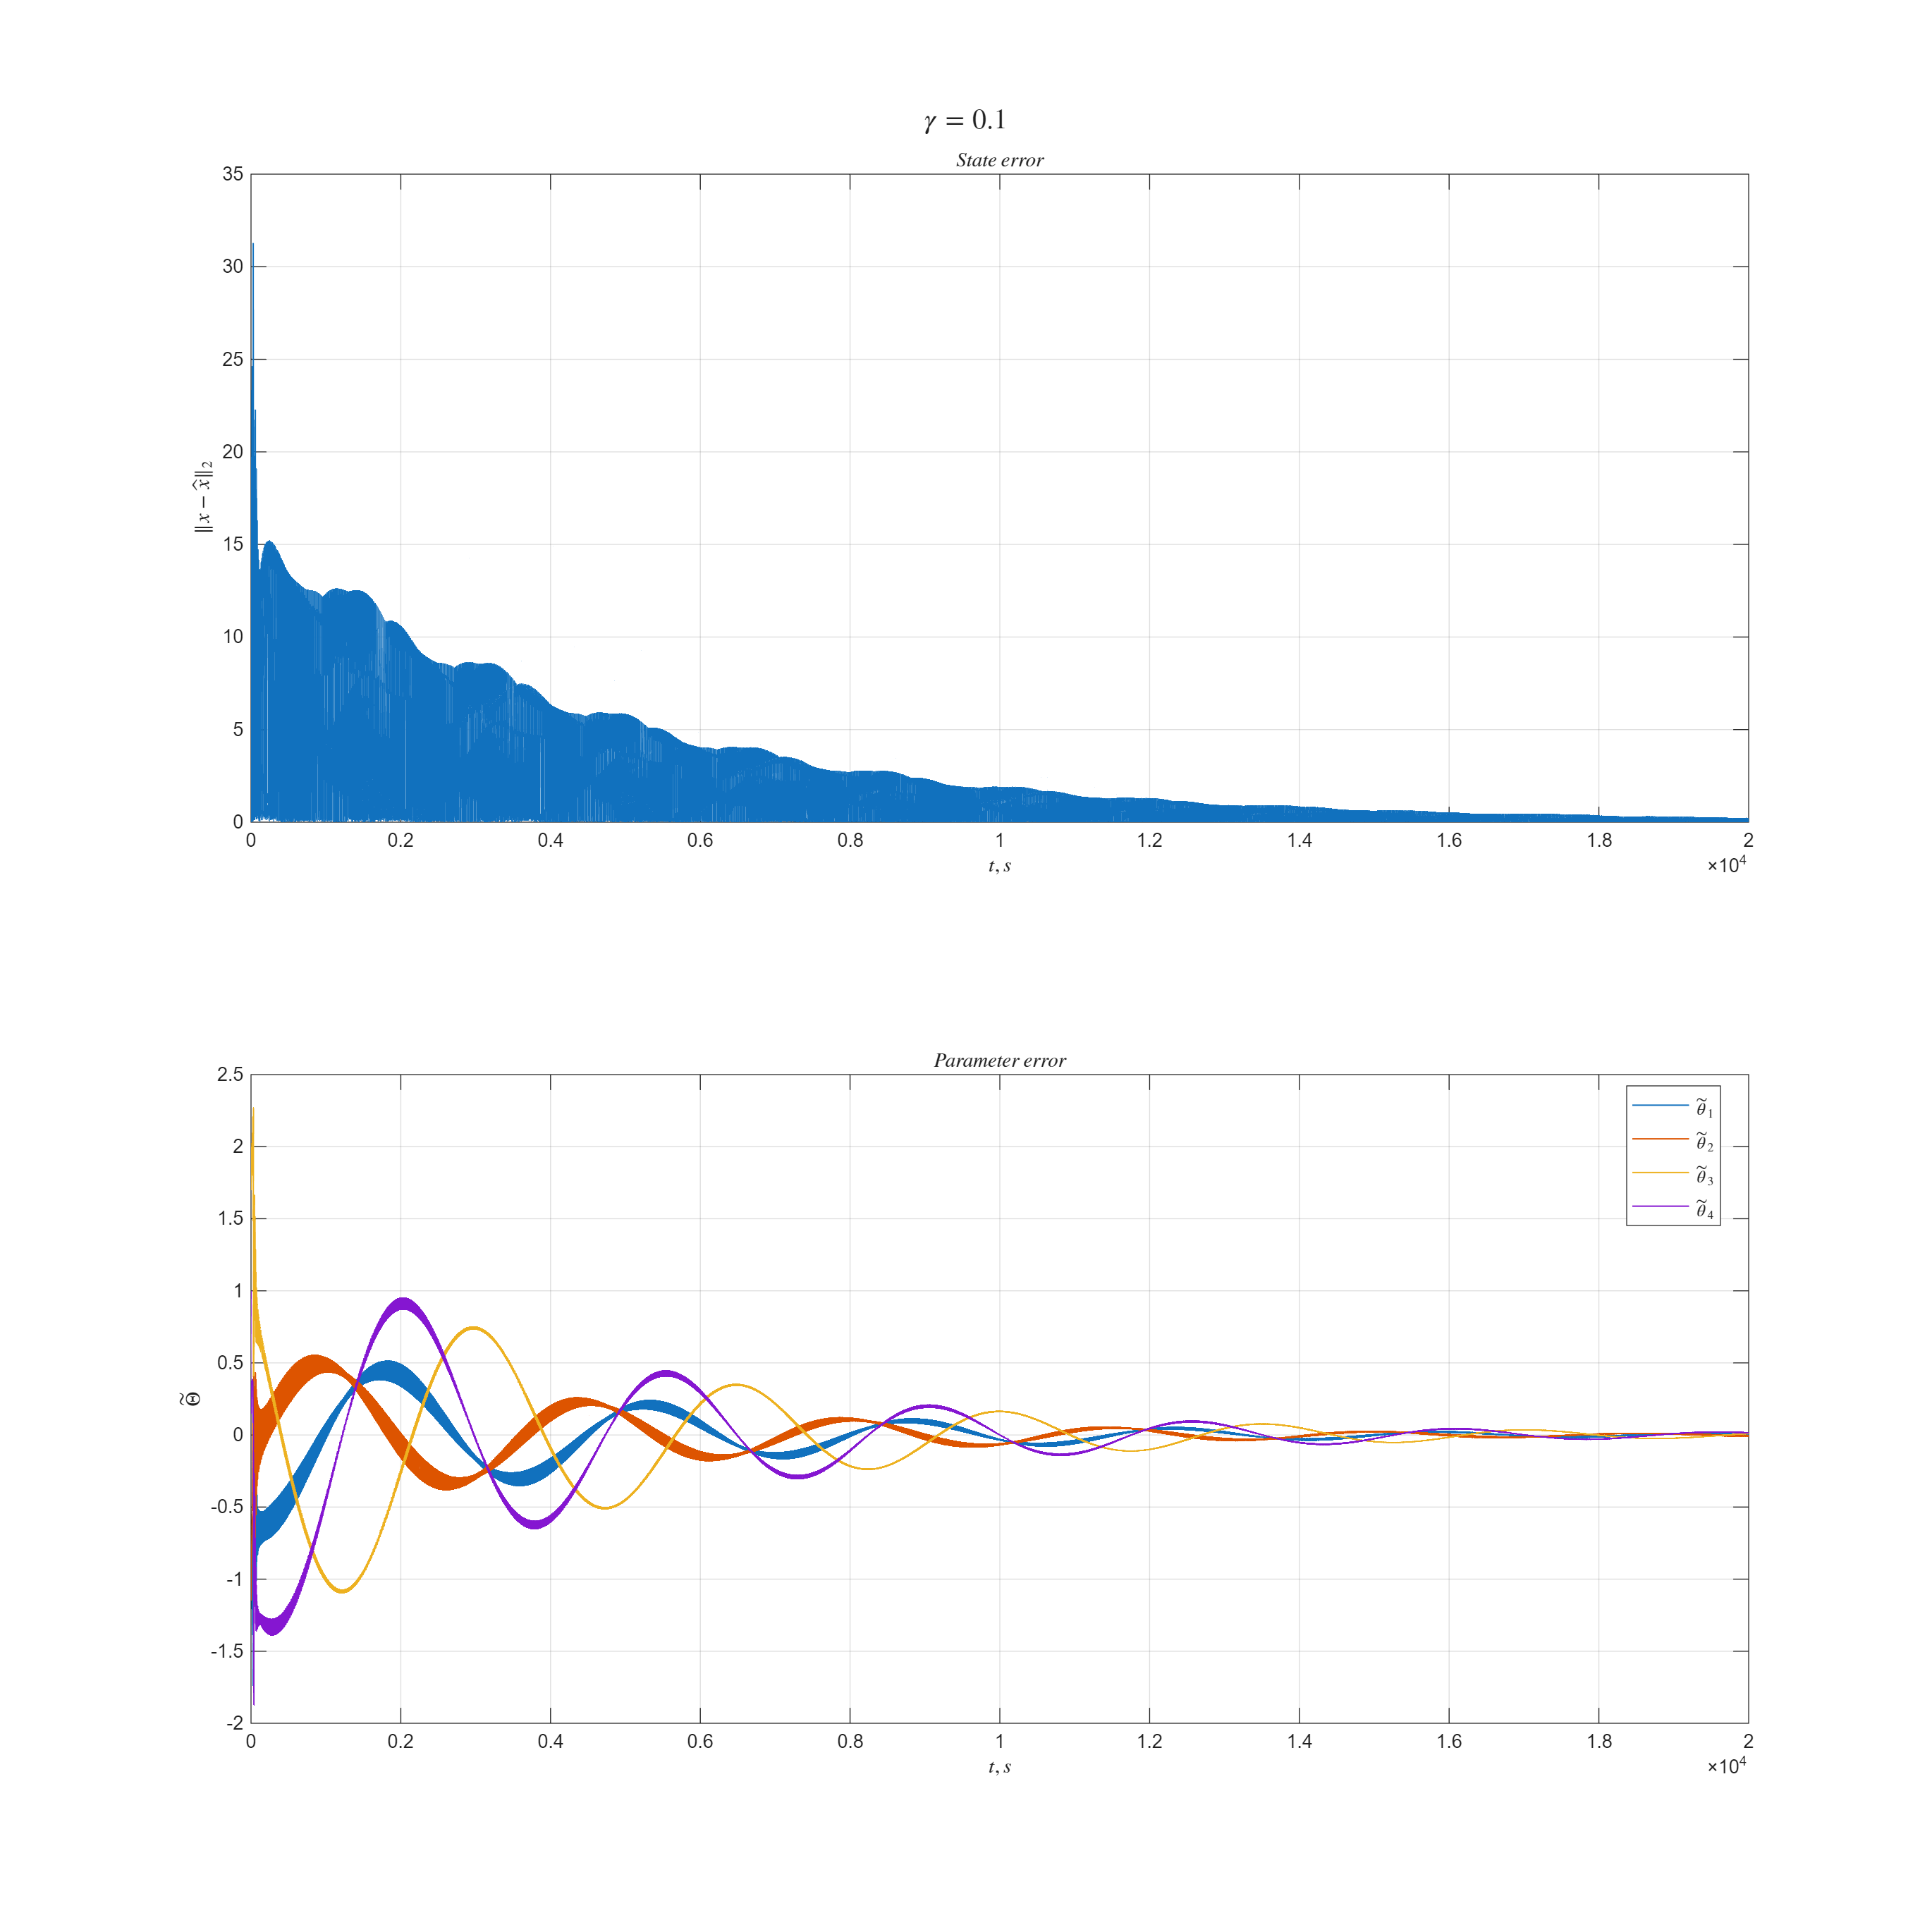

task1 = 0;
simtime = 20000;

gamma_values = [0.001 0.0025 0.004 0.005 0.1];

for gamma = gamma_values
    out = sim("lab6.slx", simtime);

    fig = figure('Position', [100, 100, 1600, 1600]);

    subplot(2,1,1);
    plot(out.state_error.Time, out.state_error.Data, LineWidth=0.75);
    xlabel("$t,s$", Interpreter="latex");
    ylabel("$\|x-\hat{x}\|_2$", Interpreter="latex");
    title("$State~error$", Interpreter="latex");
    grid on;

    subplot(2,1,2);
    plot(out.Theta_error.Time, out.Theta_error.Data, LineWidth=0.75);
    xlabel("$t,s$", Interpreter="latex");
    ylabel("$\tilde{\Theta}$", Interpreter="latex");
    title("$Parameter~error$", Interpreter="latex");
    legend(["$\tilde{\theta}_1$", "$\tilde{\theta}_2$", ...
        "$\tilde{\theta}_3$", "$\tilde{\theta}_4$"], ...
       Interpreter="latex", Location="best");
    grid on;

    sgtitle(sprintf('$\\gamma = %g$', gamma), Interpreter="latex");

    filename = sprintf('lab6_task%d_gamma_%g.png', task1, gamma);
    exportgraphics(fig, fullfile(folder, filename), 'Resolution', 600);
end